# Generación de trayectorias en el espacio cartesiano (Task-space Motion Model) y en el espacio articular (JointSpaceMotionModel)

**Trayectorias en el espacio cartesiano:**

- Se utiliza para seguir una trayectoria en el espacio determinada, por lo que la visualización del camino generado es directa y permite evitar obsctáculos conocidos.

- Requiere cinemática inversa (computacionalmente más costoso)

- Se utiliza el [taskMotionModel](https://es.mathworks.com/help/robotics/ref/taskspacemotionmodel.html) para generar este tipo de trayectorias

**Trayectorias en el espacio articular:**

- Utiliza directamente cada una de las articulaciones del robot qi (t)

- El movimiento en el espacio no es predecible (no se sigue una trayectoria en el espacio determinada), por lo que de manera directa no se puede visualizar el camino generado y se pueden evitar obstáculos conocidos.

- No requiere cinemática inversa en cada punto (menos costo computacional)

- Se utiliza el [jointMotionModel](https://es.mathworks.com/help/robotics/ref/jointspacemotionmodel.html) para generar este tipo de trayecotrias

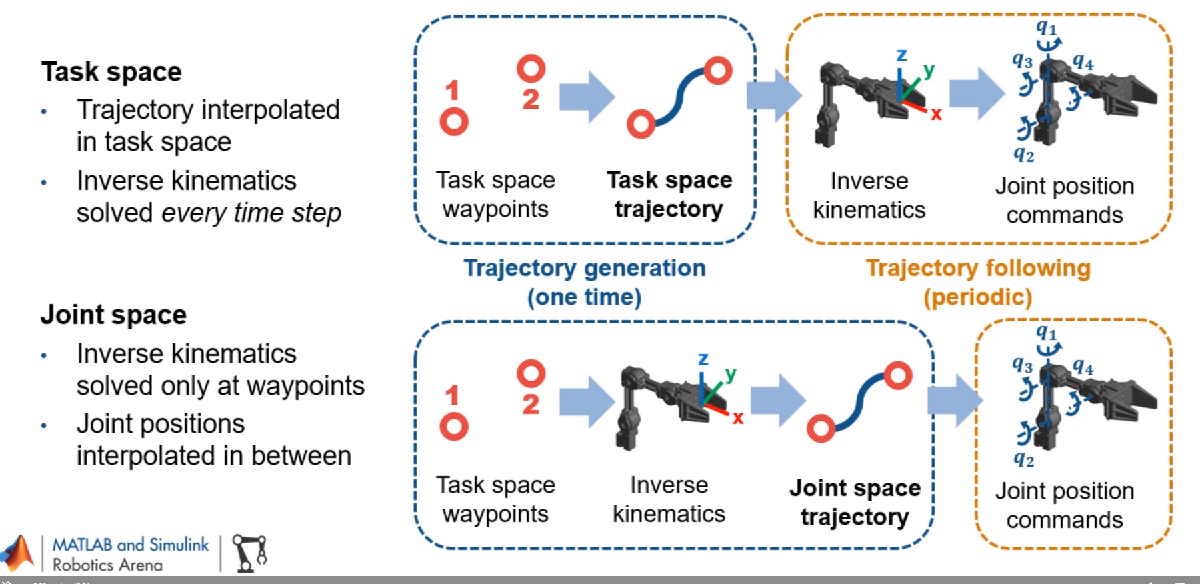

**Siulación con Matlab**

Se va a realizar la simulación del comportamiento del robot utilizandola función [derivative](https://es.mathworks.com/help/robotics/ref/jointspacemotionmodel.derivative.html) junto a un solucionador para determinar de manera eficiente la dinámica del robot. El uso del [ode15s](docid:matlab_ref.bu5yps7) permite una mayor precisión en torno a las zonas con alta tasa de cambio. También se pueden utilizar otro tipos de solucionador ([solver](https://es.mathworks.com/help/matlab/math/choose-an-ode-solver.html?searchHighlight=ode&s_tid=srchtitle_ode_7)), como por el ejemplo el [`ode45`](docid:matlab_ref.bu00_4l)`. `

La función [derivative](https://es.mathworks.com/help/robotics/ref/jointspacemotionmodel.derivative.html) calcula la derivada en el tiempo de modelos de robots, en concreto, de modelos [taskMotionModel](https://es.mathworks.com/help/robotics/ref/taskspacemotionmodel.html) o [jointMotionModel](https://es.mathworks.com/help/robotics/ref/jointspacemotionmodel.html). 

stateDot = **derivate** (taskMotionModel, state, refPose, revFel, fExt (opt))

stateDot = **derivate** (jointMotionModel, state, refPose, cmd, fExt (opt))

Parámetros

*state* (vector 1x2n): posiciones 'q' (rad) y velocidades 'dq' (rad/s) articulares del robot. Se especificaca como [q; dq]

*refPose* (matriz 4x4): matriz homogénea especificando la pose del end-effector (m)

*refVel* (6x1): Velocidades angulares 'omega' (rad/s) y velocidades lineales 'v' (m/s)  objetivo del end-effector en el espacio de trabajo. Se especefica como [omega v].

*cmd*: posición 'q', velocidad 'dq' y aceleración objetivo 'ddq'. Se especifica como [q; dq] para control PD (por defecto) y como [q; dq; ddq] para control por fuerza o de articulaciones independientes

*satateDot* (matriz de 2xn) derivada temporal del estado actual del robot de acuerdo con los parámetros de entrada especificados [dq; ddq]

Los solucionadores ecuaciones diferenciales ordinarias (ODE) tienen la siguiente sintaxis en Matlab:

[t, y] =ode45 (funcion, tspan, y0)

Por tanto, aplicando este tipo de solucionares a este problema:

`[t,state] = ode15s(@(t,state)derivative(model,state,refPose,refVel),tspan,initialState);`

`[t,state] = ode15s(@(t,state)derivative(model,state,refPose,cmd),tspan,initialState);`

Siendo *state*(matriz de 2xn): estado temporal, posición y velocidad articular, del robot. Especificado como [q, dq]

## Creación del robot

clear all
close all
robot = loadrobot("kinovaGen3","DataFormat","column","Gravity",[0 0 -9.81]); %Importar robot 
endEffector = "EndEffector_Link";
nJoints = numel (robot.homeConfiguration);
showdetails (robot)

--------------------
Robot: (8 bodies)

 Idx               Body Name         Joint Name         Joint Type               Parent Name(Idx)   Children Name(s)
 ---               ---------         ----------         ----------               ----------------   ----------------
   1           Shoulder_Link          Actuator1           revolute                   base_link(0)   HalfArm1_Link(2)  
   2           HalfArm1_Link          Actuator2           revolute               Shoulder_Link(1)   HalfArm2_Link(3)  
   3           HalfArm2_Link          Actuator3           revolute               HalfArm1_Link(2)   ForeArm_Link(4)  
   4            ForeArm_Link          Actuator4           revolute               HalfArm2_Link(3)   Wrist1_Link(5)  
   5             Wrist1_Link          Actuator5           revolute                ForeArm_Link(4)   Wrist2_Link(6)  
   6             Wrist2_Link          Actuator6           revolute                 Wrist1_Link(5)   Bracelet_Link(7)  
   7           Br

## Establecer parámetros de simulación

Establecer intervalo de tiempo para la simulación de 1 segundo con un periodo de 0.02 segundos. Establecer el estado inicial del robot como una matriz columna [ángulos articulaciones, velocidad articulaciones]. 

tspan = 0:0.02:2; %Crear vector de tiempo
initialState = [homeConfiguration(robot);zeros(nJoints,1)];

Establecemos el ángulo objetivo de las articulaciones del robot. A partir de estos ángulos, se obtiene posición objetivo del end-effector con la función getTransform.

targetJoints = [pi/4; pi/3; pi/2; -pi/3; pi/4; -pi/4; 3*pi/4];
refPose = getTransform (robot, targetJoints, endEffector);

Podemos hacerlo al revés. Definimos el punto objetivo y calculamos los ángulos articulares objetivo mediante la cinemática inversa.

% refPoint = [0.6 -.1 0.5];
% refPose = trvec2tform(refPoint);
% ik = inverseKinematics('RigidBodyTree', robot);
% weights = [0.1, 0.1, 0., 1, 1, 1];
% qInitial = homeConfiguration(robot); % Use home configuration as the initial guess
% targetJoints = ik(endEffector,trvec2tform(refPoint),weights,qInitial);
    

# Trayectorias en el espacio cartesiano (Task-Space Motion Model)

El objetivo es crear y usar un objeto de tipo `taskSpaceMotionModel` para mover un robot manipulador en el espacio.

## Creación del modelo de movimiento en el espacio de trabajo

motionModel_TS = taskSpaceMotionModel("RigidBodyTree",robot,"EndEffectorName",endEffector);

## Simulación del robot

Simulación del comportamiento del robot utilizando un solucionador para determinar de manera eficiente la dinámica del robot. El uso del [ode15s](docid:matlab_ref.bu5yps7) permite una mayor precisión en torno a las zonas con alta tasa de cambio. También se pueden utilizar otro tipos de solucionador ([solver](https://es.mathworks.com/help/matlab/math/choose-an-ode-solver.html?searchHighlight=ode&s_tid=srchtitle_ode_7)), como por el ejemplo el [`ode45`](docid:matlab_ref.bu00_4l) 

% Definir la velocidad objetivo del end-effector en el espacio de trabajo [omega v]
refVel = zeros(6,1);
[t,robotState_TS] = ode15s(@(t,state)derivative(motionModel_TS,state,refPose,refVel),tspan,initialState);

# Trayectorias en el espacio articular (Joint-Space Motion Model)

## Creación del modelo de movimiento en el espacio articular

motionModel_JS = jointSpaceMotionModel("RigidBodyTree",robot);

## Simulación del robot

Utilizamos la función derivative del modelo definido como entrada al solucionador ode15 para simular el comportamiento del robot durante 1 segundo.

%Establecemos el estado objetivo del robot [ángulos, velocidad, aceleracion] de las articulaciones
targetState = [targetJoints; zeros(nJoints,1); zeros(nJoints,1)];
%stateDot = derivative(jointMotionModel,state,cmds)
[t,robotState_JS] = ode15s(@(t,state)derivative(motionModel_JS,state,targetState),tspan,initialState);

# Visualización de la simulación del robot

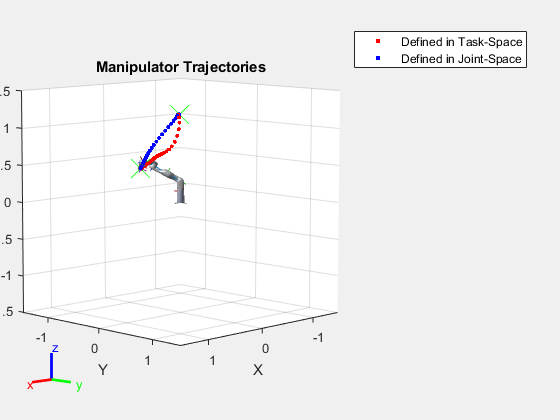

figure
set(gcf,'Visible','on')
%nJoints = motionModel_JS.NumJoin
show(robot,initialState(1:nJoints));
hold all
initPose = getTransform (robot, initialState(1:nJoints), endEffector);
plot3(initPose(1,4),initPose(2,4),initPose(3,4),'x','Color','g',"MarkerSize",20)
plot3(refPose(1,4),refPose(2,4),refPose(3,4),"x",'Color','g',"MarkerSize",20)
r = rateControl(5);

%TASK-SPACE MODEL
for i = 1:size(robotState_TS,1)
    poseNow = getTransform(robot,robotState_TS(i,1:nJoints)',endEffector);
    show(robot,robotState_TS(i,1:nJoints)',"PreservePlot",false);
    taskSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',10);
    waitfor(r);
end

%JOINT-SPACE MODEL
for i = 1:size(robotState_JS,1)
    poseNow = getTransform(robot,robotState_JS(i,1:nJoints)',endEffector);
    show(robot,robotState_JS(i,1:nJoints)',"PreservePlot",false);
    jointSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',10);
    waitfor(r);
end
% Add a legend and title
legend([taskSpaceMarker jointSpaceMarker], {'Defined in Task-Space', 'Defined in Joint-Space'});
title('Manipulator Trajectories')

## Graficar las posiciones articulares del robot 

Graficar las posiciones de todas las articulaciones desde su posición inicial a su posición final. 

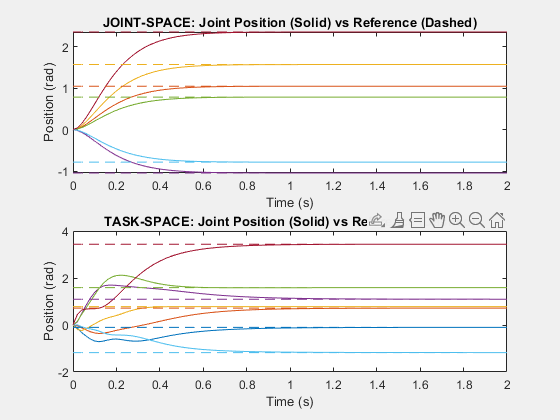

figure
set(gcf,'Visible','on')
subplot (2,1,1)
plot(t,robotState_JS(:,1:nJoints));
hold all;
plot(t,targetState(1:nJoints)*ones(1,length(t)),"--");
title("JOINT-SPACE: Joint Position (Solid) vs Reference (Dashed)");
xlabel("Time (s)")
ylabel("Position (rad)");

subplot (2,1,2)
plot(t,robotState_TS(:,1:nJoints));
hold all;
plot(t,robotState_TS(length (robotState_TS),1:nJoints)'*ones(1,length(t)),"--");
title("TASK-SPACE: Joint Position (Solid) vs Reference (Dashed)");
xlabel("Time (s)")
ylabel("Position (rad)");

## Graficar las velocidades articulares del robot 

Graficar las velocidades de todas las articulaciones desde su posición inicial a su posición final. Se puede observar que las articulaciones con mayor desplazamiento entre la posición inicial y final alcanzan velocidades mas altas. Esto puede ocasionar sobrepicos, aunque el control de todas las articulaciones tenga el mismo tiempo de establecimiento fijado.

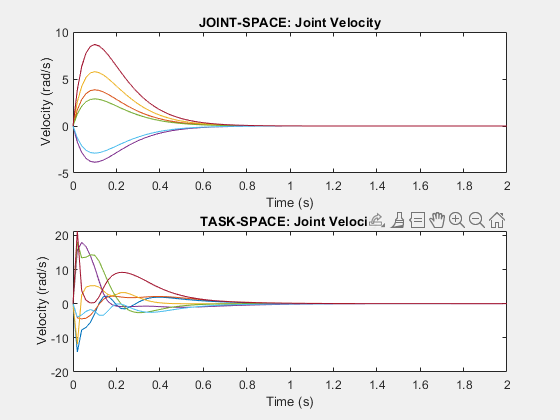

figure
set(gcf,'Visible','on')
subplot (2,1,1)
plot(t,robotState_JS(:,nJoints+1:nJoints*2));
title("JOINT-SPACE: Joint Velocity");
xlabel("Time (s)")
ylabel("Velocity (rad/s)");

subplot (2,1,2)
plot(t,robotState_TS(:,nJoints+1:nJoints*2));
title("TASK-SPACE: Joint Velocity");
xlabel("Time (s)")
ylabel("Velocity (rad/s)");